%% Análisis de componentes principales de las sintonizaciones del PID proporcional
% Este live script aplica el análisis de componentes principales (PCA) al
% archivo *SINTONIZACIONES.csv*, generado mediante Algoritmo Genético, con
% el propósito de identificar la relación existente entre las covariables
% del paciente (edad, peso, altura y sexo) y las constantes del controlador
% PID proporcional (Kp, Ki, Kd y γ).
%
% El PCA se aplica de forma conjunta sobre las ocho variables. Si una
% componente principal concentra simultáneamente cargas elevadas de
% covariables y de constantes, ello constituye un indicio de que dichas
% variables varían de forma coordinada entre pacientes. El análisis se
% complementa con la matriz de correlación directa y con la correlación
% reconstruida a partir de las componentes retenidas.
%

%% 1. Configuración general
% Todos los parámetros del análisis y el diseño de las figuras se concentran
% en esta sección. 
% =========================================================================
% CONFIGURACIÓN GLOBAL
% =========================================================================
clear; clc; close all;

% ── Rutas ────────────────────────────────────────────────────────────────
rutaSintonizaciones = "SINTONIZACIONES.csv";      % Archivo de sintonizaciones
rutaGraficas        = "C:\Users\yordi\Desktop";   % Carpeta de destino de las figuras
guardarFiguras      = false;                      % true = exportar cada figura en PNG
resolucionFiguras   = 300;                        % Resolución de exportación [ppp]

% ── Selección de registros ───────────────────────────────────────────────
% Se excluyen los registros cuyo RMSE supera este umbral, dado que una
% sintonización deficiente no refleja de manera fiable la relación entre
% las características del paciente y las constantes del controlador.

umbralRMSE = 16;

% ── Variables del análisis ───────────────────────────────────────────────
covariables          = ["Edad", "Peso", "Altura", "Sexo_num"];
constantes           = ["Kp", "Ki", "Kd", "gamma"];
etiquetasCovariables = ["Edad", "Peso", "Altura", "Sexo"];
etiquetasConstantes  = ["Kp", "Ki", "Kd", "γ"];

% ── Parámetros del análisis ──────────────────────────────────────────────
tipoCorrelacion    = "Pearson";  % "Pearson" o "Spearman"
alfa               = 0.05;       % Nivel de significancia
umbralVarianza     = 80;         % Varianza acumulada mínima [%] para retener componentes
umbralCarga        = 0.50;       % |carga| mínima para considerar dominante una variable
componentesGrafica = [1 2];      % Componentes del círculo de correlaciones y del biplot

% =========================================================================
% ESTILOS DE LAS FIGURAS  
% =========================================================================
% Los colores se expresan como tripletas RGB con valores entre 0 y 1.

% ── Tipografía ───────────────────────────────────────────────────────────
estilo.fuente          = "Helvetica";
estilo.tamanoFuente    = 11;
estilo.tamanoTitulo    = 13;
estilo.tamanoEtiquetas = 11;          % Rótulos de los vectores de variables

% ── Colores de los grupos de variables ───────────────────────────────────
estilo.colorCovariables = [1.00 0.08 0.58];
estilo.colorConstantes  = [0.05 0.93 0.10];

% ── Gráficos de varianza explicada ───────────────────────────────────────
estilo.colorBarras    = [0.30 0.60 0.85];
estilo.colorAcumulada = [0.80 0.10 0.20];
estilo.colorUmbral    = [0.40 0.40 0.40];
estilo.anchoLinea     = 1.8;

% ── Mapas de calor ───────────────────────────────────────────────────────
estilo.mapaCorrelacion = mapaDivergente(256);   % Azul (−1) · blanco (0) · rojo (+1)
estilo.formatoCeldas   = "%.2f";                % Formato numérico de las celdas

% ── Puntos de los pacientes en el biplot ─────────────────────────────────
estilo.colorearPuntosPor = "sexo";              % "sexo" o "rmse"
estilo.colorHombres      = [0.20 0.45 0.80];
estilo.colorMujeres      = [0.90 0.40 0.30];
estilo.mapaPuntos        = "parula";            % Mapa de color en el modo "rmse"
estilo.tamanoMarcador    = 30;
estilo.opacidadPuntos    = 0.65;

% ── Vectores de las variables ────────────────────────────────────────────
estilo.anchoVector          = 1.8;
estilo.tamanoPunta          = 0.35;             % Tamaño relativo de la punta de flecha
estilo.escalaVectoresBiplot = 0.85;             % Fracción del alcance de los puntos

% ── Figura ───────────────────────────────────────────────────────────────
estilo.tamanoFigura = [100 100 900 650];        % [x y ancho alto] en píxeles
estilo.colorFondo   = [1 1 1];

%% 2. Carga y depuración de los datos
% Se lee el archivo de sintonizaciones, se codifica numéricamente el sexo (M → 0, F → 1). A
% continuación se descartan los registros cuyo RMSE supera el umbral
% establecido y aquellos que contengan valores faltantes.

% =========================================================================
% LECTURA Y VERIFICACIÓN DEL ARCHIVO
% =========================================================================
T = readtable(rutaSintonizaciones, "TextType", "string");

columnasRequeridas = ["Edad", "Peso", "Altura", "Sexo", ...
                      "Kp", "Ki", "Kd", "gamma", "RMSE"];
faltantes = setdiff(columnasRequeridas, string(T.Properties.VariableNames));
if ~isempty(faltantes)
    error("El archivo no contiene las columnas: %s.", strjoin(faltantes, ", "));
end

% Codificación numérica del sexo: 'M' → 0, 'F' → 1
sexoTexto = upper(strtrim(string(T.Sexo)));
if any(~ismember(sexoTexto, ["M", "F"]))
    error("Se encontraron valores de Sexo distintos de 'M' o 'F'.");
end
T.Sexo_num = double(sexoTexto == "F");

% =========================================================================
% SELECCIÓN DE REGISTROS
% =========================================================================
nTotal = height(T);
T = T(T.RMSE <= umbralRMSE, :);
T = rmmissing(T, "DataVariables", cellstr([covariables, constantes]));
n = height(T);

variables = [covariables, constantes];
etiquetas = [etiquetasCovariables, etiquetasConstantes];
nc = numel(covariables);        % Número de covariables
nk = numel(constantes);         % Número de constantes del controlador
p  = nc + nk;                   % Número total de variables

if n <= p
    error("El número de registros (%d) debe ser mayor que el de variables (%d).", n, p);
end

fprintf("Registros en el archivo        : %d\n", nTotal);

Registros en el archivo        : 340


fprintf("Registros con RMSE ≤ %-9g : %d (%.1f %%)\n", umbralRMSE, n, 100 * n / nTotal);

Registros con RMSE ≤ 16        : 290 (85.3 %)


fprintf("   Hombres                     : %d\n", sum(T.Sexo_num == 0));

   Hombres                     : 134


fprintf("   Mujeres                     : %d\n", sum(T.Sexo_num == 1));

   Mujeres                     : 156



%% 3. Análisis descriptivo y correlación directa
% Antes de aplicar el PCA se presenta un resumen descriptivo de las
% variables y la matriz de correlación entre cada covariable y cada
% constante del controlador. Esta matriz constituye la referencia contra la
% cual se contrastará posteriormente la estructura identificada por el PCA.
%
% La variable Sexo es binaria; su coeficiente de correlación de Pearson con
% una variable continua equivale al coeficiente biserial puntual, e indica
% si la constante correspondiente tiende a ser mayor en mujeres (valor
% positivo) o en hombres (valor negativo).

% =========================================================================
% RESUMEN DESCRIPTIVO
% =========================================================================
X = T{:, cellstr(variables)};

resumen = table(mean(X)', std(X)', min(X)', median(X)', max(X)', ...
    'VariableNames', {'Media', 'DesvEstandar', 'Minimo', 'Mediana', 'Maximo'}, ...
    'RowNames', cellstr(etiquetas))

resumen = 8×5 table
                Media      DesvEstandar     Minimo      Mediana     Maximo 
              _________    ____________    ________    _________    _______

    Edad         58.428        14.286            18           59         90
    Peso         61.403        12.107          34.1         59.5        109
    Altura       161.33        8.9201         140.2       161.05      184.6
    Sexo        0.53793       0.49942             0            1          1
    Kp           1.7781       0.70791      0.079656        1.816          3
    Ki        0.0054853      0.013416         1e-08    0.0021463    0.13648
    Kd            1.481       0.78782         1e-08        1.517          3
    <s

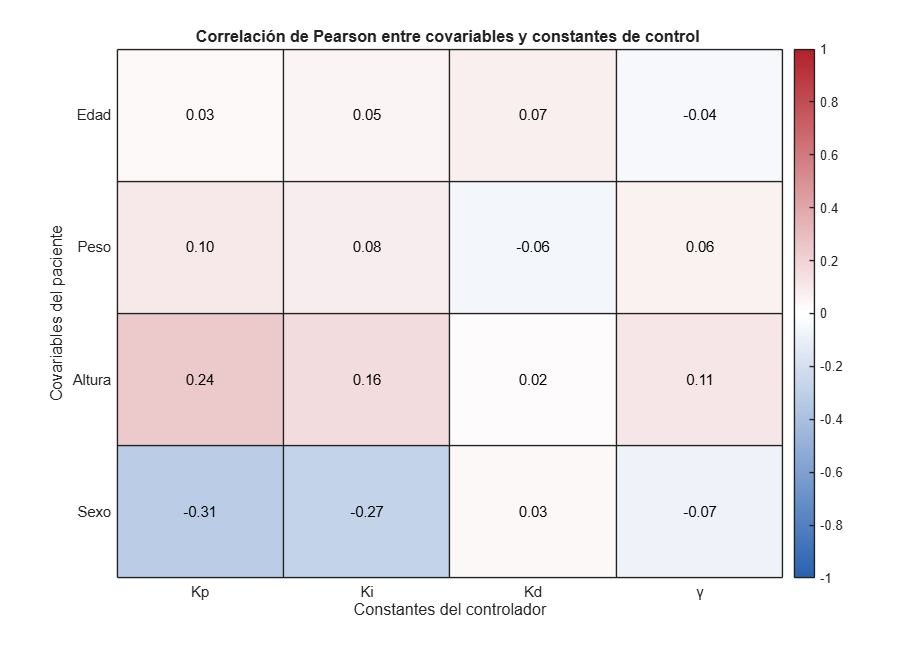


% =========================================================================
% CORRELACIÓN ENTRE COVARIABLES Y CONSTANTES DEL CONTROLADOR
% =========================================================================
[R, P] = corr(X, "Type", char(tipoCorrelacion));
Rcruzada = R(1:nc, nc+1:end);           % Filas: covariables · Columnas: constantes
Pcruzada = P(1:nc, nc+1:end);

fig = figure("Name", "Correlación directa", "Position", estilo.tamanoFigura, ...
             "Color", estilo.colorFondo);
h = heatmap(cellstr(etiquetasConstantes), cellstr(etiquetasCovariables), Rcruzada);
h.Colormap        = estilo.mapaCorrelacion;
h.ColorLimits     = [-1 1];
h.CellLabelFormat = char(estilo.formatoCeldas);
h.FontName        = char(estilo.fuente);
h.FontSize        = estilo.tamanoFuente;
h.Title  = sprintf("Correlación de %s entre covariables y constantes de control ", ...
                   tipoCorrelacion);
h.XLabel = "Constantes del controlador";
h.YLabel = "Covariables del paciente";

guardarFigura(fig, "pca_01_correlacion_directa", rutaGraficas, ...
              guardarFiguras, resolucionFiguras);

% Tabla de pares ordenada por la magnitud de la correlación
[iCov, iCon] = ndgrid(1:nc, 1:nk);
pares = table(etiquetasCovariables(iCov(:))', etiquetasConstantes(iCon(:))', ...
              Rcruzada(:), Pcruzada(:), ...
              'VariableNames', {'Covariable', 'Constante', 'r', 'ValorP'});
pares.Significativa = pares.ValorP < alfa;
pares = sortrows(pares, "r", "descend", "ComparisonMethod", "abs")

pares = 16×5 table
    Covariable    Constante        r          ValorP      Significativa
    __________    _________    _________    __________    _____________

     "Sexo"         "Kp"        -0.31442    4.4867e-08        true     
     "Sexo"         "Ki"          -0.275    1.9864e-06        true     
     "Altura"       "Kp"         0.23726    4.4772e-05        true     
     "Altura"       "Ki"         0.16333     0.0053007        true     
     "Altura"       "γ"          0.10975      0.061973        false    
     "Peso"         "Kp"         0.10497      0.074284        false    
     "Peso"         "Ki"        0.079673       0.17603        false    
     "Edad"         "Kd"        0.074208       0.20767        false    
     "Sexo"         "γ"        -0.073585       0.21152        false    
     "Peso"       


%% 4. Estandarización y cálculo de las componentes principales
% Dado que las variables poseen escalas muy distintas (por ejemplo, Ki
% adopta valores del orden de 10⁻³ mientras que el peso se mide en decenas
% de kilogramos), cada variable se estandariza a media cero y desviación
% estándar unitaria antes del análisis. De este modo, el PCA opera sobre la
% matriz de correlación y todas las variables contribuyen en igualdad de
% condiciones.
%
% Cuando se selecciona la correlación de Spearman, el PCA se aplica sobre
% los rangos de las variables, de manera que el análisis resulta coherente
% con dicho coeficiente y menos sensible a valores atípicos.
%
% Las cargas se calculan como el producto de cada coeficiente por la raíz
% cuadrada del autovalor de su componente. Al trabajar con variables
% estandarizadas, la carga de una variable sobre una componente coincide con
% la correlación entre ambas, por lo que toma valores entre −1 y 1.

% =========================================================================
% ESTANDARIZACIÓN
% =========================================================================
if tipoCorrelacion == "Spearman"
    Xpca = tiedrank(X);                 % Rangos por columna
else
    Xpca = X;
end

desviaciones = std(Xpca);
if any(desviaciones == 0)
    error("Las variables %s no presentan variabilidad en los registros seleccionados.", ...
          strjoin(etiquetas(desviaciones == 0), ", "));
end
Z = zscore(Xpca);

% =========================================================================
% ANÁLISIS DE COMPONENTES PRINCIPALES
% =========================================================================
[coeficientes, puntuaciones, autovalores, ~, varianzaExplicada] = pca(Z);
varianzaAcumulada = cumsum(varianzaExplicada);

% Cargas: correlación entre cada variable (filas) y cada componente (columnas)
cargas = coeficientes .* sqrt(autovalores');

%% 5. Varianza explicada y número de componentes retenidas
% Se reportan dos criterios de retención: el criterio de Kaiser, que
% conserva las componentes con autovalor mayor que uno, y el criterio de
% varianza acumulada, que conserva el menor número de componentes cuya
% varianza acumulada alcanza el umbral establecido. En el resto del análisis
% se emplea el segundo criterio, con un mínimo de dos componentes.

% =========================================================================
% CRITERIOS DE RETENCIÓN
% =========================================================================
nKaiser    = sum(autovalores > 1);
nVarianza  = find(varianzaAcumulada >= umbralVarianza, 1, "first");
nRetenidas = max(nVarianza, 2);

tablaVarianza = table((1:p)', autovalores, varianzaExplicada, varianzaAcumulada, ...
    'VariableNames', {'Componente', 'Autovalor', 'VarianzaExplicada', 'VarianzaAcumulada'})

tablaVarianza = 8×4 table
    Componente    Autovalor    VarianzaExplicada    VarianzaAcumulada
    __________    _________    _________________    _________________

        1           2.4075          30.094               30.094      
        2           1.2496           15.62               45.714      
        3           1.0786          13.482               59.196      
        4          0.93156          11.644               70.841      
        5          0.85438           10.68                81.52      
        6          0.79147          9.8934               91.414      
        7          0.49941          6.2426               97.656      
        8           0.1875          2.3437                  100      



fprintf("Criterio de Kaiser (autovalor > 1)       : %d componentes\n", nKaiser);

Criterio de Kaiser (autovalor > 1)       : 3 componentes


fprintf("Criterio de varianza acumulada (≥ %g %%) : %d componentes\n", ...
        umbralVarianza, nVarianza);

Criterio de varianza acumulada (≥ 80 %) : 5 componentes


fprintf("Componentes retenidas para el análisis   : %d (%.1f %% de la varianza)\n", ...
        nRetenidas, varianzaAcumulada(nRetenidas));

Componentes retenidas para el análisis   : 5 (81.5 % de la varianza)


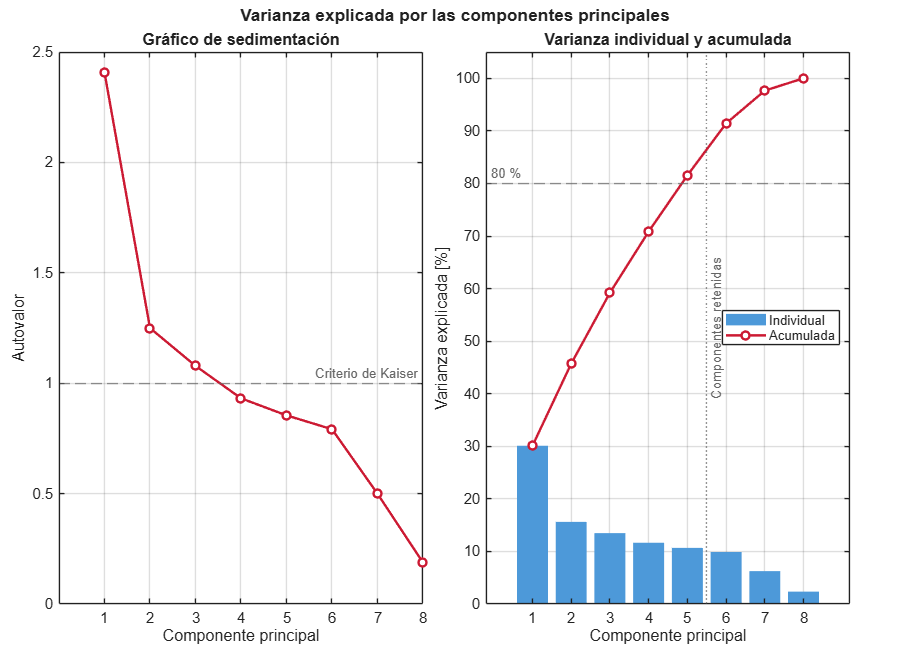


% =========================================================================
% FIGURA — GRÁFICO DE SEDIMENTACIÓN Y VARIANZA EXPLICADA
% =========================================================================
fig = figure("Name", "Varianza explicada", "Position", estilo.tamanoFigura, ...
             "Color", estilo.colorFondo);
tl = tiledlayout(1, 2, "TileSpacing", "compact", "Padding", "compact");
title(tl, "Varianza explicada por las componentes principales", ...
      "FontSize", estilo.tamanoTitulo, "FontWeight", "bold");

% Panel izquierdo: autovalores y criterio de Kaiser
ax1 = nexttile(tl);
plot(ax1, 1:p, autovalores, "-o", "Color", estilo.colorAcumulada, ...
     "LineWidth", estilo.anchoLinea, "MarkerFaceColor", "w");
hold(ax1, "on");
yline(ax1, 1, "--", "Criterio de Kaiser", "Color", estilo.colorUmbral, ...
      "LabelHorizontalAlignment", "right");
xlabel(ax1, "Componente principal");
ylabel(ax1, "Autovalor");
title(ax1, "Gráfico de sedimentación");
xticks(ax1, 1:p);
grid(ax1, "on");

% Panel derecho: varianza individual y acumulada
ax2 = nexttile(tl);
bar(ax2, 1:p, varianzaExplicada, "FaceColor", estilo.colorBarras, "EdgeColor", "none");
hold(ax2, "on");
plot(ax2, 1:p, varianzaAcumulada, "-o", "Color", estilo.colorAcumulada, ...
     "LineWidth", estilo.anchoLinea, "MarkerFaceColor", "w");
yline(ax2, umbralVarianza, "--", sprintf("%g %%", umbralVarianza), ...
      "Color", estilo.colorUmbral, "LabelHorizontalAlignment", "left");
xline(ax2, nRetenidas + 0.5, ":", "Componentes retenidas", ...
      "Color", estilo.colorUmbral, "LabelVerticalAlignment", "middle");
xlabel(ax2, "Componente principal");
ylabel(ax2, "Varianza explicada [%]");
title(ax2, "Varianza individual y acumulada");
legend(ax2, ["Individual", "Acumulada"], "Location", "east");
xticks(ax2, 1:p);
ylim(ax2, [0 105]);
grid(ax2, "on");

set([ax1 ax2], "FontName", estilo.fuente, "FontSize", estilo.tamanoFuente);

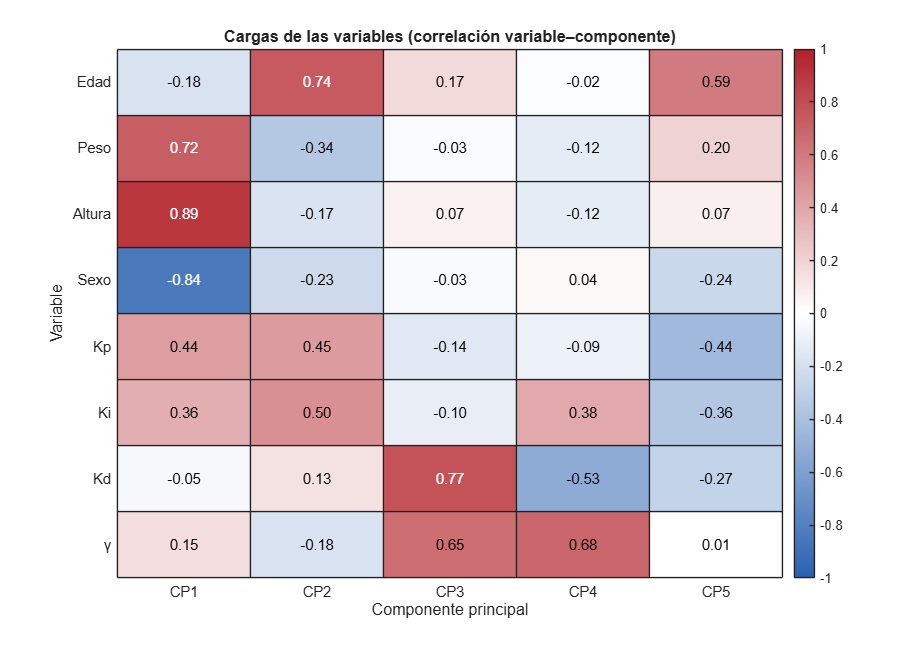

guardarFigura(fig, "pca_02_varianza_explicada", rutaGraficas, ...
              guardarFiguras, resolucionFiguras);

%% 6. Cargas de las variables sobre las componentes retenidas
% El mapa de calor muestra la correlación de cada variable con cada
% componente retenida. Una componente es relevante para el objetivo del
% estudio cuando presenta cargas elevadas, en valor absoluto, tanto en
% covariables como en constantes del controlador: ello indica que ambos
% grupos de variables varían conjuntamente en la población.
%
% Observación: el signo de cada componente es arbitrario; lo que resulta
% interpretable es el signo relativo entre las cargas de una misma
% componente. Dos variables con cargas del mismo signo tienden a aumentar
% conjuntamente, mientras que signos opuestos indican una relación inversa.

% =========================================================================
% FIGURA — MAPA DE CALOR DE LAS CARGAS
% =========================================================================
nombresComponentes = compose("CP%d", 1:nRetenidas);

fig = figure("Name", "Cargas", "Position", estilo.tamanoFigura, ...
             "Color", estilo.colorFondo);
h = heatmap(cellstr(nombresComponentes), cellstr(etiquetas), cargas(:, 1:nRetenidas));
h.Colormap        = estilo.mapaCorrelacion;
h.ColorLimits     = [-1 1];
h.CellLabelFormat = char(estilo.formatoCeldas);
h.FontName        = char(estilo.fuente);
h.FontSize        = estilo.tamanoFuente;
h.Title  = "Cargas de las variables (correlación variable–componente)";
h.XLabel = "Componente principal";
h.YLabel = "Variable";

guardarFigura(fig, "pca_03_cargas", rutaGraficas, guardarFiguras, resolucionFiguras);

tablaCargas = array2table(cargas(:, 1:nRetenidas), ...
    'VariableNames', cellstr(nombresComponentes), 'RowNames', cellstr(etiquetas))

tablaCargas = 8×5 table
                 CP1         CP2          CP3          CP4          CP5   
              _________    ________    _________    _________    _________

    Edad       -0.17998     0.74108      0.16984    -0.016267      0.59291
    Peso        0.71936    -0.34489    -0.028233     -0.12185       0.1995
    Altura      0.89481    -0.17209     0.068886     -0.12404     0.074781
    Sexo       -0.84223    -0.22708    -0.031813     0.036448     -0.24432
    Kp          0.43637     0.44836     -0.14118    -0.090098     -0.44275
    Ki          0.36459     0.49843      -0.1038      0.38453     -0.35543
    Kd        -0.045679     0.13337      0.76732     -0.52995     -0.27455
    

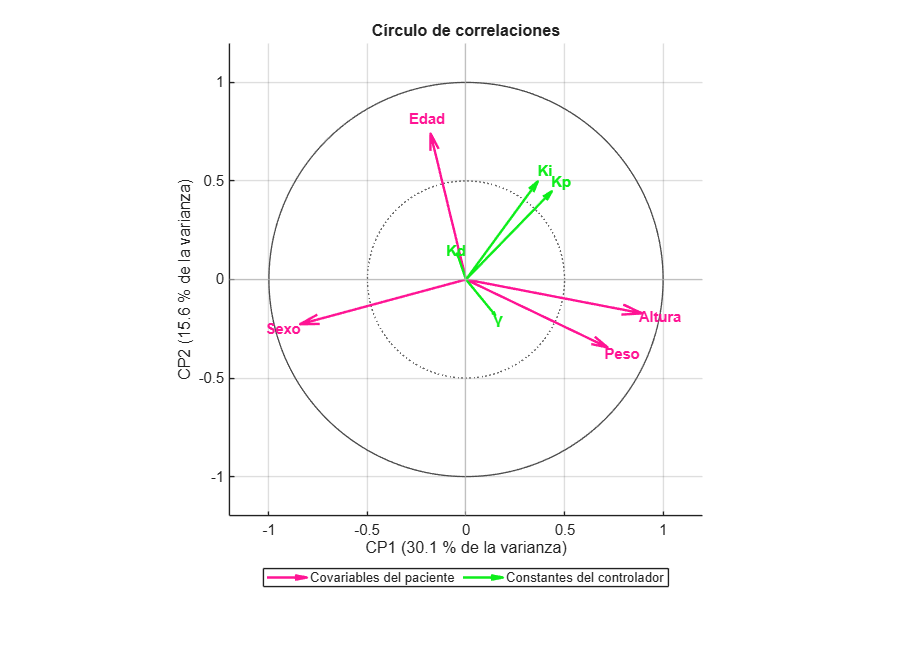


%% 7. Círculo de correlaciones
% Cada variable se representa como un vector cuyas coordenadas son sus
% cargas sobre las dos componentes seleccionadas. La longitud del vector indica qué tan bien queda representada
% la variable en el plano (un vector próximo a la circunferencia unitaria
% está bien representado); el ángulo entre dos vectores aproxima su
% correlación, de modo que vectores próximos indican correlación positiva,
% vectores opuestos indican correlación negativa y vectores perpendiculares
% indican ausencia de relación.
%
% Por consiguiente, la relación entre las covariables del paciente (en azul)
% y las constantes del controlador (en naranja) puede leerse directamente a
% partir de los ángulos que forman sus vectores.

% =========================================================================
% FIGURA — CÍRCULO DE CORRELACIONES
% =========================================================================
cx = componentesGrafica(1);
cy = componentesGrafica(2);

fig = figure("Name", "Círculo de correlaciones", "Position", estilo.tamanoFigura, ...
             "Color", estilo.colorFondo);
ax = axes(fig);
hold(ax, "on");

% Circunferencias de referencia (radio 1 y radio 0.5) y ejes
theta = linspace(0, 2*pi, 400);
plot(ax, cos(theta), sin(theta), "-", "Color", [0.30 0.30 0.30], "LineWidth", 1);
plot(ax, 0.5*cos(theta), 0.5*sin(theta), ":", "Color", estilo.colorUmbral);
xline(ax, 0, "-", "Color", [0.70 0.70 0.70]);
yline(ax, 0, "-", "Color", [0.70 0.70 0.70]);

% Vectores de las variables
manejadores = gobjects(1, 2);
for j = 1:p
    if j <= nc
        color = estilo.colorCovariables;  grupo = 1;
    else
        color = estilo.colorConstantes;   grupo = 2;
    end
    manejadores(grupo) = quiver(ax, 0, 0, cargas(j, cx), cargas(j, cy), 0, ...
        "Color", color, "LineWidth", estilo.anchoVector, ...
        "MaxHeadSize", estilo.tamanoPunta);
    text(ax, 1.10 * cargas(j, cx), 1.10 * cargas(j, cy), etiquetas(j), ...
         "Color", color, "FontWeight", "bold", "FontSize", estilo.tamanoEtiquetas, ...
         "HorizontalAlignment", "center", "VerticalAlignment", "middle");
end

axis(ax, "equal");
xlim(ax, [-1.2 1.2]);
ylim(ax, [-1.2 1.2]);
xlabel(ax, sprintf("CP%d (%.1f %% de la varianza)", cx, varianzaExplicada(cx)));
ylabel(ax, sprintf("CP%d (%.1f %% de la varianza)", cy, varianzaExplicada(cy)));
title(ax, "Círculo de correlaciones", "FontSize", estilo.tamanoTitulo);
legend(ax, manejadores, ["Covariables del paciente", "Constantes del controlador"], ...
       "Location", "southoutside", "Orientation", "horizontal");
grid(ax, "on");
set(ax, "FontName", estilo.fuente, "FontSize", estilo.tamanoFuente);

guardarFigura(fig, "pca_04_circulo_correlaciones", rutaGraficas, ...
              guardarFiguras, resolucionFiguras);

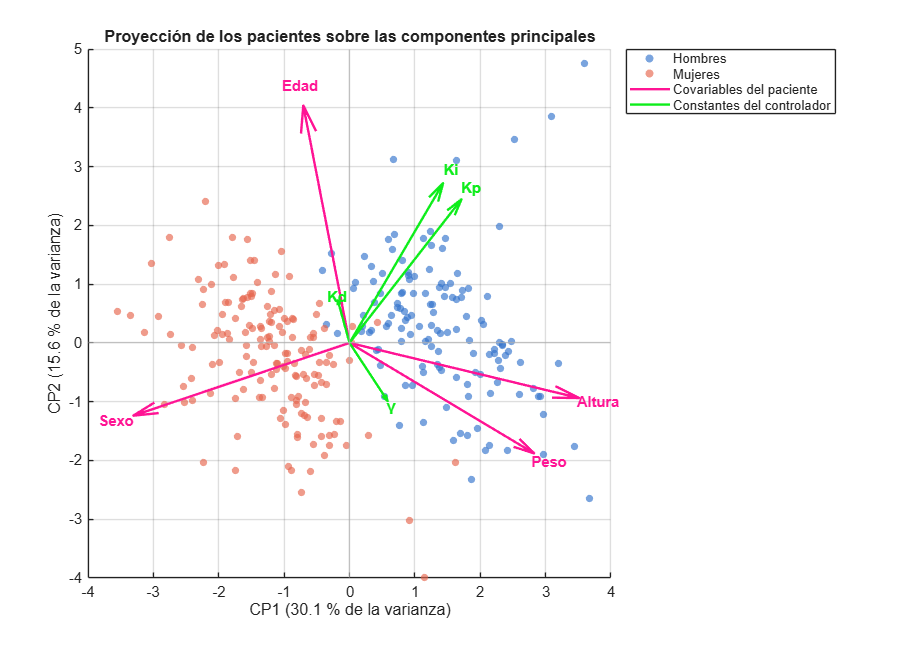


%% 8. Proyección de los pacientes (biplot)
% Cada punto representa a un paciente proyectado sobre las dos componentes
% seleccionadas; los vectores indican la dirección en la que crece cada
% variable. Los pacientes situados en la dirección de un vector presentan
% valores elevados de la variable correspondiente. 

% =========================================================================
% FIGURA — BIPLOT
% =========================================================================
fig = figure("Name", "Biplot", "Position", estilo.tamanoFigura, ...
             "Color", estilo.colorFondo);
ax = axes(fig);
hold(ax, "on");

puntos = puntuaciones(:, [cx cy]);

% Proyección de los pacientes
switch estilo.colorearPuntosPor
    case "sexo"
        esMujer = T.Sexo_num == 1;
        scatter(ax, puntos(~esMujer, 1), puntos(~esMujer, 2), estilo.tamanoMarcador, ...
                estilo.colorHombres, "filled", "MarkerFaceAlpha", estilo.opacidadPuntos, ...
                "DisplayName", "Hombres");
        scatter(ax, puntos(esMujer, 1), puntos(esMujer, 2), estilo.tamanoMarcador, ...
                estilo.colorMujeres, "filled", "MarkerFaceAlpha", estilo.opacidadPuntos, ...
                "DisplayName", "Mujeres");
    case "rmse"
        scatter(ax, puntos(:, 1), puntos(:, 2), estilo.tamanoMarcador, T.RMSE, ...
                "filled", "MarkerFaceAlpha", estilo.opacidadPuntos, ...
                "DisplayName", "Pacientes");
        colormap(ax, char(estilo.mapaPuntos));
        barra = colorbar(ax);
        barra.Label.String = "RMSE";
    otherwise
        error("El valor de estilo.colorearPuntosPor debe ser ""sexo"" o ""rmse"".");
end

% Vectores de las variables, escalados al alcance de los puntos
escala = estilo.escalaVectoresBiplot * max(abs(puntos), [], "all") / ...
         max(abs(coeficientes(:, [cx cy])), [], "all");
for j = 1:p
    if j <= nc
        color = estilo.colorCovariables;
    else
        color = estilo.colorConstantes;
    end
    u = escala * coeficientes(j, cx);
    v = escala * coeficientes(j, cy);
    quiver(ax, 0, 0, u, v, 0, "Color", color, "LineWidth", estilo.anchoVector, ...
           "MaxHeadSize", estilo.tamanoPunta, "HandleVisibility", "off");
    text(ax, 1.08 * u, 1.08 * v, etiquetas(j), "Color", color, "FontWeight", "bold", ...
         "FontSize", estilo.tamanoEtiquetas, "HorizontalAlignment", "center");
end

% Elementos auxiliares para la leyenda de los grupos de variables
plot(ax, NaN, NaN, "-", "Color", estilo.colorCovariables, ...
     "LineWidth", estilo.anchoVector, "DisplayName", "Covariables del paciente");
plot(ax, NaN, NaN, "-", "Color", estilo.colorConstantes, ...
     "LineWidth", estilo.anchoVector, "DisplayName", "Constantes del controlador");

xline(ax, 0, "-", "Color", [0.70 0.70 0.70], "HandleVisibility", "off");
yline(ax, 0, "-", "Color", [0.70 0.70 0.70], "HandleVisibility", "off");
xlabel(ax, sprintf("CP%d (%.1f %% de la varianza)", cx, varianzaExplicada(cx)));
ylabel(ax, sprintf("CP%d (%.1f %% de la varianza)", cy, varianzaExplicada(cy)));
title(ax, "Proyección de los pacientes sobre las componentes principales", ...
      "FontSize", estilo.tamanoTitulo);
legend(ax, "Location", "bestoutside");
grid(ax, "on");
set(ax, "FontName", estilo.fuente, "FontSize", estilo.tamanoFuente);

guardarFigura(fig, "pca_05_biplot", rutaGraficas, guardarFiguras, resolucionFiguras);






%% 9. Interpretación de las componentes retenidas
% Para cada componente retenida se enumeran las variables dominantes, es
% decir, aquellas cuya carga supera en valor absoluto el umbral establecido.
% Cuando una componente reúne covariables y constantes dominantes, se
% clasifica como mixta y se describe el sentido de la relación sugerida.

% =========================================================================
% INTERPRETACIÓN DE LAS COMPONENTES
% =========================================================================
fprintf("Umbral de carga dominante: |carga| ≥ %.2f\n\n", umbralCarga);

Umbral de carga dominante: |carga| ≥ 0.50




for k = 1:nRetenidas
    dominantes = find(abs(cargas(:, k)) >= umbralCarga)';
    covDom = dominantes(dominantes <= nc);
    conDom = dominantes(dominantes >  nc);

    fprintf("CP%d  (%.1f %% de la varianza)\n", k, varianzaExplicada(k));
    if isempty(dominantes)
        fprintf("   Sin variables dominantes.\n\n");
        continue
    end

    textoVariables = strings(1, numel(dominantes));
    for m = 1:numel(dominantes)
        j = dominantes(m);
        textoVariables(m) = sprintf("%s (%+.2f)", etiquetas(j), cargas(j, k));
    end
    fprintf("   Variables dominantes: %s\n", strjoin(textoVariables, ", "));

    if ~isempty(covDom) && ~isempty(conDom)
        fprintf("   → Componente mixta: vincula covariables y constantes del controlador.\n");
        for ic = covDom
            for jc = conDom
                if sign(cargas(ic, k) * cargas(jc, k)) > 0
                    tendencia = "mayor";
                else
                    tendencia = "menor";
                end
                if covariables(ic) == "Sexo_num"
                    fprintf("      · En mujeres, %s tiende a ser %s que en hombres.\n", ...
                            etiquetas(jc), tendencia);
                else
                    fprintf("      · A mayor %s, %s tiende a ser %s.\n", ...
                            lower(etiquetas(ic)), etiquetas(jc), tendencia);
                end
            end
        end
    elseif ~isempty(covDom)
        fprintf("   → Componente asociada únicamente a covariables del paciente.\n");
    else
        fprintf("   → Componente asociada únicamente a constantes del controlador.\n");
    end
    fprintf("\n");
end

CP1  (30.1 % de la varianza)


   Variables dominantes: Peso (+0.72), Altura (+0.89), Sexo (-0.84)


   → Componente asociada únicamente a covariables del paciente.


CP2  (15.6 % de la varianza)


   Variables dominantes: Edad (+0.74)


   → Componente asociada únicamente a covariables del paciente.


CP3  (13.5 % de la varianza)


   Variables dominantes: Kd (+0.77), γ (+0.65)


   → Componente asociada únicamente a constantes del controlador.


CP4  (11.6 % de la varianza)


   Variables dominantes: Kd (-0.53), γ (+0.68)


   → Componente asociada únicamente a constantes del controlador.


CP5  (10.7 % de la varianza)


   Variables dominantes: Edad (+0.59)


   → Componente asociada únicamente a covariables del paciente.



%% Funciones auxiliares

function mapa = mapaDivergente(n)
% MAPADIVERGENTE  Genera un mapa de color divergente azul–blanco–rojo,
% adecuado para representar magnitudes simétricas respecto de cero, como
% los coeficientes de correlación y las cargas.
%
%   mapa = mapaDivergente(n) devuelve una matriz de n×3 con valores RGB.
    if nargin < 1
        n = 256;
    end
    azul   = [0.16 0.38 0.69];
    blanco = [1.00 1.00 1.00];
    rojo   = [0.70 0.13 0.16];
    mitad  = floor(n / 2);
    t1 = linspace(0, 1, mitad)';
    t2 = linspace(0, 1, n - mitad)';
    mapa = [azul + (blanco - azul) .* t1; blanco + (rojo - blanco) .* t2];
end

function guardarFigura(fig, nombre, ruta, guardar, resolucion)
% GUARDARFIGURA  Exporta la figura en formato PNG cuando así se indica en
% la configuración general.
    if ~guardar
        return
    end
    archivo = fullfile(ruta, nombre + ".png");
    exportgraphics(fig, archivo, "Resolution", resolucion);
    fprintf("[INFO] Figura guardada: %s\n", archivo);
end